Week 9 Day 1 Example, expanding on last week's quiz. Construct full Xn and plot the spectra

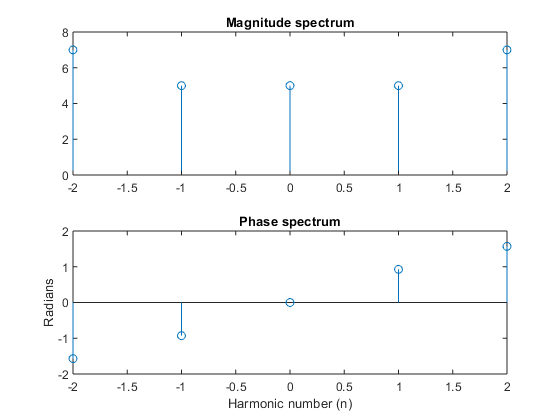

X = [5 3+1j*4 1j*7]; % n = 0..2
X = [conj(X(3:-1:2)) X]; % since x(n) is real
n = -2:2;
figure
subplot(2,1,1),stem(n,abs(X))
title('Magnitude spectrum')
subplot(2,1,2),stem(n,angle(X))
title('Phase spectrum'),ylabel('Radians')
xlabel('Harmonic number (n)')

Now, build the signal from the exponential form of the Fourier series. Since we have a conjugate symmetric series, the resulting signal is theoretically real

w0 = 1; % not on quiz, arbitrary
T0 = 2*pi/w0;
t = linspace(-T0,T0); % calculate 2 periods
x = zeros(size(t));
for idx=1:length(n)
    x = x + X(idx) * exp(1j*n(idx)*w0*t);    
end
fprintf('The norm of the real portion of the signal is %g and of the imaginary portion is %g.\n',...
    norm(real(x)), norm(imag(x)))

The norm of the real portion of the signal is 131.332 and of the imaginary portion is 3.99106e-15.


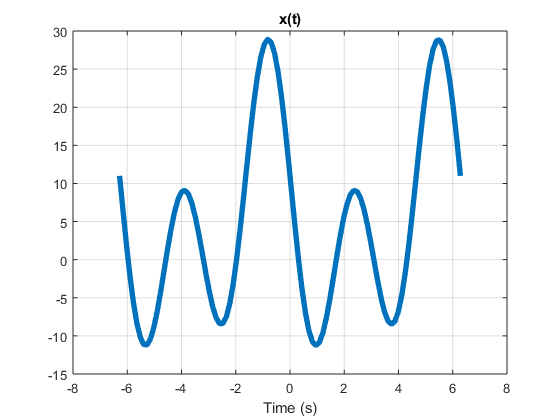

assert(norm(imag(x)) < 1e-13, 'Unexpected: imaginary portion of x(t) is significant. Construction error?')
x = real(x); % discard imaginary portion *after* confirming negligible
figure
plot(t,x), grid, title('x(t)')
xlabel('Time (s)')